## Random Forest Tests

### Initialise

% CLear all, load the dataset
clear
clc
clf
close all
% loads the letter dataset 
% 
load letterDatasetClass.mat
letterDataset = letterDatasetStandardisedReducedFeatures;
disp(letterDataset);

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×12 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×13 table]
                trainTable: [16000×13 table]
                 testTable: [4000×13 table]
            isStandardised: 1
          isRemovedFeature: 1



### Check Random Forest Analysis Code Works

hyperParameters = RFHyperparameters.getHyperQuickInstance();

rfHyperparameters =   RFHyperparameters with properties:

      features: [2 4]
         trees: 25
         folds: [2 3]
    randomSeed: 122


rfClass = RandomForestClass(hyperParameters);
rfClass.debug = true;
results = rfClass.performAnalysis(letterDataset, "RFQuickTest.csv");

Starting Random Forest analysis...
Misclassified 179 entries out of 3200. 5.5938 pct	Training loss: 0.01. Test Loss: 0.09 Oob Error: 0.18	Precision: 0.9435 Recall: 0.9441 Accuracy: 0.9441 F1: 0.9438
	numTree 25 numFeature 2 trainErr 0.0100 testErr 0.0855 oobErr 0.1825 fold 1  of 2 	Samples: T I D N G
Misclassified 164 entries out of 3200. 5.1250 pct	Training loss: 0.01. Test Loss: 0.08 Oob Error: 0.18	Precision: 0.9482 Recall: 0.9488 Accuracy: 0.9487 F1: 0.9485
	numTree 25 numFeature 2 trainErr 0.0098 testErr 0.0824 oobErr 0.1839 fold 2  of 2 	Samples: T I D N A
Misclassified 160 entries out of 3200. 5.0000 pct	Training loss: 0.01. Test Loss: 0.08 Oob Error: 0.19	Precision: 0.9498 Recall: 0.9498 Accuracy: 0.9500 F1: 0.9498
	numTree 25 numFeature 2 trainErr 0.0107 testErr 0.0819 oobErr 0.1861 fold 1  of 3 	Samples: T I G A M
Misclassified 142 entries out of 3200. 4.4375 pct	Training loss: 0.01. Test Loss: 0.08 Oob Error: 0.18	Precision: 0.9550 Recall: 0.9555 Accuracy: 0.9556 F1: 0.9552


disp(results.resultsTable);

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________

       2        25       2              1               0.0099          0.084         0.1832        0.9464          0.9459        0.9465      0.9462       3200         13.672   
       2        25     

### Hyperparameter Optimization Search

hyperParameters = RFHyperparameters.getHyperDefaultInstance();
rfClass = RandomForestClass(hyperParameters);
rfClass.debug = true;
results = rfClass.performAnalysis(letterDataset, "RFDefaultTest.csv");

Starting Random Forest analysis...
Misclassified 152 entries out of 3200. 4.7500 pct	Training loss: 0.01. Test Loss: 0.07 Oob Error: 0.12	Precision: 0.9521 Recall: 0.9527 Accuracy: 0.9525 F1: 0.9524
	numTree 50 numFeature 2 trainErr 0.0052 testErr 0.0681 oobErr 0.1240 fold 1  of 2 	Samples: T I D N G
Misclassified 140 entries out of 3200. 4.3750 pct	Training loss: 0.01. Test Loss: 0.06 Oob Error: 0.13	Precision: 0.9557 Recall: 0.9560 Accuracy: 0.9563 F1: 0.9559
	numTree 50 numFeature 2 trainErr 0.0052 testErr 0.0643 oobErr 0.1257 fold 2  of 2 	Samples: T I D N A
Misclassified 145 entries out of 3200. 4.5313 pct	Training loss: 0.01. Test Loss: 0.06 Oob Error: 0.13	Precision: 0.9541 Recall: 0.9549 Accuracy: 0.9547 F1: 0.9545
	numTree 50 numFeature 2 trainErr 0.0057 testErr 0.0648 oobErr 0.1264 fold 1  of 3 	Samples: T I G A M
Misclassified 128 entries out of 3200. 4.0000 pct	Training loss: 0.01. Test Loss: 0.06 Oob Error: 0.13	Precision: 0.9594 Recall: 0.9599 Accuracy: 0.9600 F1: 0.9596


    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________

       2        50       2              1               0.0052         0.0662         0.1249        0.9544          0.9539        0.9544      0.9541       3200         24.313   
       2        50     

results = RFResults.getInstanceFromCsvResults("RFDefaultTest.csv");
disp(results.resultsTable);

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________

       2        50       2              1               0.0052         0.0662         0.1249        0.9544          0.9539        0.9544      0.9541       3200         24.313   
       2        50     

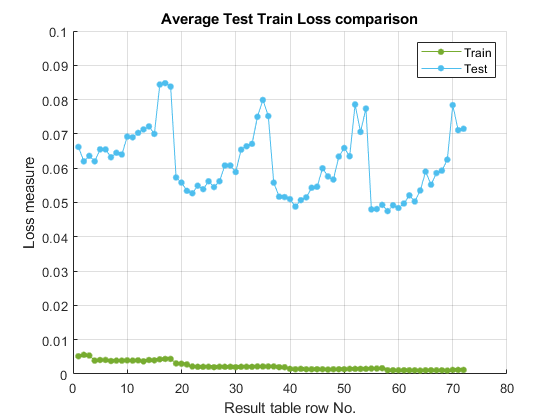

PlotUtil.plotLossTestTrainComparisonWithYMax(results.resultsTable, "Average Test Train Loss comparison", 0.1);

Rows 58, 41 and 22 look interesting: smallest loss in their group. The results for these rows is shown below:

disp(results.resultsTable([58,41,22],:));

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________

       4       200       2             58               0.0011         0.0475         0.0658        0.9589          0.9585        0.9592      0.9589       3200         107.69   
       4       150     

As stated by [1] and [2], 100 trees is the minimum acceptable, more trees gives slightly better results, but takes considerably longer.

[3] report that the number of folds has little effect on prediction using decision trees, in fact they report that the only reason they use two folds is that using one fold is not a reccomended statistical practise.

The number of features that perform best are 4.

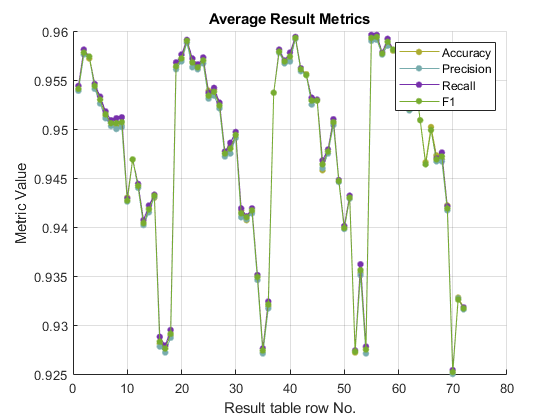

PlotUtil.plotMetrics(results.resultsTable, "Average Result Metrics");

Rows 17, 35, 54, 70 look interesting

disp(results.resultsTable([58,41,22],:));

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________

       4       200       2             58               0.0011         0.0475         0.0658        0.9589          0.9585        0.9592      0.9589       3200         107.69   
       4       150     

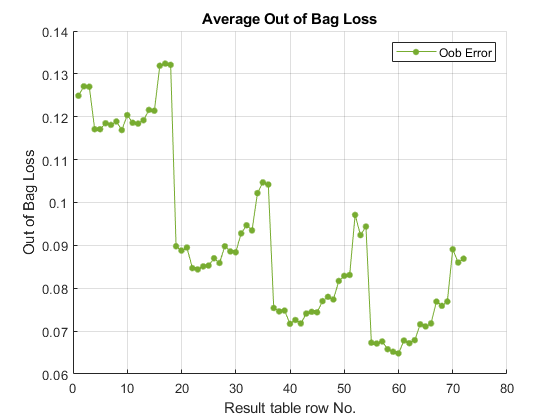


PlotUtil.plotOob(results.resultsTable, "Average Out of Bag Loss");

Rows 40, 60 look interesting

disp(results.resultsTable([40,60],:));

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________

       4       150       2             40               0.0015          0.051         0.0717         0.957          0.9569        0.9578      0.9574       3200         81.172   
       4       200     

The two hyperparameters which affect the result are folds, and number of trees.  The difference in oob loss is small (less sthan 1%) but the time taken to train the models is consierable. 150 trees looks like the candidate to select for the number of trees.

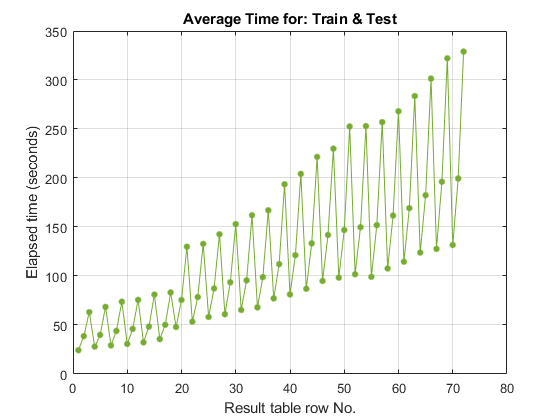

PlotUtil.plotTime(results.resultsTable, "Average Time for: Train & Test")

A repeated pattern is apparent, with low, medium and high times. Which hyperparameter is found by looking at the details below:

disp(results.resultsTable([22,23,24],:));

    feature    tree    folds    randomTreebagSeed    avgTrainLoss    avgTestLoss    avgOobLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime
    _______    ____    _____    _________________    ____________    ___________    __________    ___________    ____________    _________    ______    __________    ___________

       4       100       2             22               0.0022         0.0527         0.0847        0.9572          0.9563        0.9572      0.9568       3200         53.422   
       4       100     

The results show that the number of folds was the predominant factor for the time difference. The number of folds affects the time taken to grow the tree.

### Train TreeBagger Model

rng(1);
model = TreeBagger(50, letterDataset.trainTable, "TargetAscii", ...
  "OOBPrediction", "On", ...
  "OOBPredictorImportance", "On", ...
  'PredictorSelection','curvature', ...
  "Method", "classification")

model =   TreeBagger
Ensemble with 50 bagged decision trees:
                    Training X:           [16000x12]
                    Training Y:            [16000x1]
                        Method:       classification
                 NumPredictors:                   12
         NumPredictorsToSample:                    4
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    1
                     Proximity:                   []
                    ClassNames:             'A'             'B'             'C'             'D'             'E'             'F'             'G'             'H'             'I'             'J'             'K'             'L'             'M'             'N'             'O'             'P'             'Q'          

### Plot out-of-bag error / number of trees

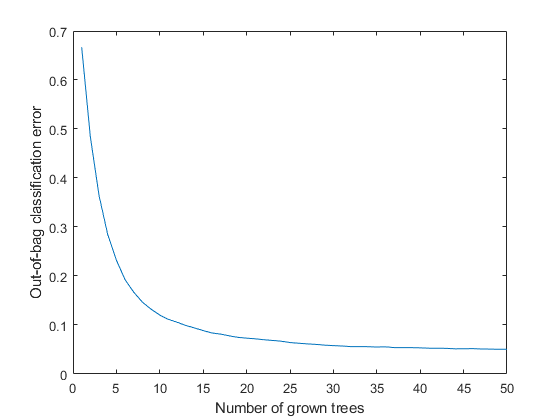

figure;
oobErrorBaggedEnsemble = oobError(model);
plot(oobErrorBaggedEnsemble)
xlabel 'Number of grown trees';
ylabel 'Out-of-bag classification error';

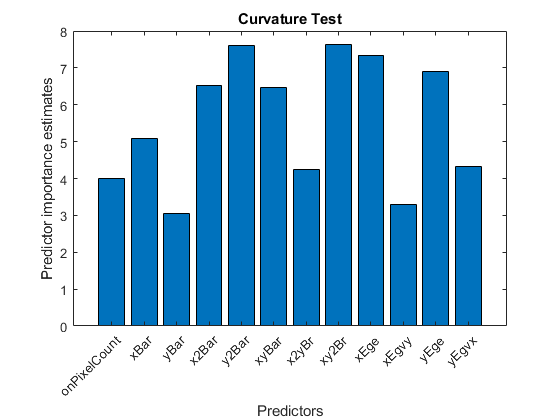


% plot predictor importances
imp = model.OOBPermutedPredictorDeltaError;

figure;
bar(imp);
title('Curvature Test');
ylabel('Predictor importance estimates');
xlabel('Predictors');
h = gca;
h.XTickLabel = model.PredictorNames;
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';

### Notes

TreeBagger has several properties of interest:

- `NumPredictorsToSample: number of features to randomly select for each tree, default sqrt(num classes)`

- `NumTrees: the number of trees in the forest`

- `Prior: prior distribution of the classes, this is set to the empirical distribution of the entire training dataset classes`

`Number of trees in the ensemble: Khoshgoftaar (2007) a default value of 100 for trees is good.`

`Braiman (2001): more trees will give better results without overfitting on the validation set.`

`Number of random features for splitting at each step: Khoshgoftarr (2007) (log2 * numFeatures + 1). Matlab uses sqrt(numFeatures)`

### `References`

`[1] Breiman, L., Adele Cutler, `[Random forests - classification description (berkeley.edu)](https://www.stat.berkeley.edu/~breiman/RandomForests/cc_home.htm)

[2] T. M. Khoshgoftaar, M. Golawala, and J. V. Hulse, “An Empirical Study of Learning from Imbalanced Data Using Random Forest,” 

[3] P. W. Frey and D. J. Slate, “Letter recognition using Holland-style adaptive classifiers,” *Mach. Learn.*, vol. 6, no. 2, pp. 161–182, Mar. 1991, doi: 10.1007/BF00114162.